clear
clf
sine = @(x,A,f,phi) A.*sin(2.*pi.*f.*x + phi);
lengthx = 2;
dx = 0.001;
x = 0:dx:lengthx;%-dx;
N = numel(x);

Recall that $y=A\;\sin \left(2\pi \;f\;x\;+\;\phi \right)=A\;\sin \left(\omega \;x\;+\;\phi \right)$,

where   $A=\textrm{amplitude}$

            
$$f=\textrm{frequency}\;\left(\textrm{cycles}\;\textrm{per}\;\_\_\_\right)$$


            $\omega =\mathrm{angular}\;\mathrm{frequency}\;\left(\mathrm{radians}\;\mathrm{per}\;\_\_\_\right)$     [$\omega =2\pi \;f$]

            
$$\phi =\textrm{phase}\;\textrm{offset}\;\left(\textrm{radians}\right)$$


First, we'll generate a "continuous" sine wave (see note below). Play with the parameters if you aren't clear on how they affect the shape of the sine wave function.

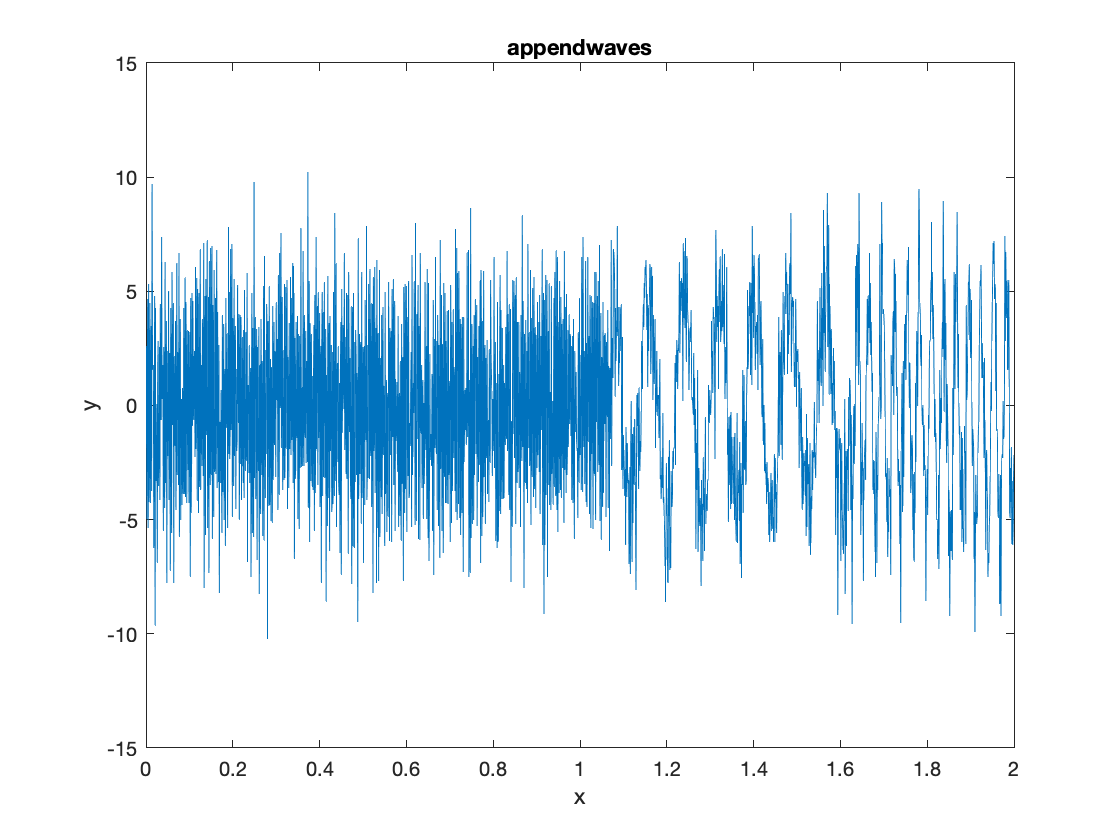

Noise = 2.*randn(size(x));
approach = 'appendwaves';

%Set underlying sine function parameters
A1 = 5; %amplitude
f1 = 370.6; %frequency
phi1 = 0; %phase
prc1 = 1; %100%

A2 = 5; %amplitude
f2 = 12.3; %frequency
phi2 = 0; %phase
prc2 = 51./100;

A3 = 5; %amplitude
f3 = 34.9; %frequency
phi3 = 0.4; %phase
prc3 = 35./100;

Amplitude = [A1 A2 A3]';
Frequency = [f1 f2 f3]';
Phase = [phi1 phi2 phi3]';
RelativePercent = [prc1 prc2 prc3]';
TotalPercent = [prc1 prc2 prc3]'./sum([prc1 prc2 prc3]);

T = table(Amplitude,Frequency,Phase,RelativePercent,TotalPercent);

%Generate dataset
if strcmp(approach,'sumwaves')
    y1 = sine(x,A1,f1,phi1);
    y2 = sine(x(1:ceil(prc2*N)),A2,f2,phi2);
    y3 = sine(x(1:ceil(prc3*N)),A3,f3,phi3);
    y = y1 + [y2 zeros(1,floor((1-prc2)*N))] + [y3 zeros(1,floor((1-prc3)*N))] + Noise;
elseif strcmp(approach,'appendwaves') % length is percent of
    N1 = round(N/(1+prc2+prc3));
    N2 = round(prc2*N1);
    N3 = N-N1-N2;
    y1 = sine(x(1:N1),A1,f1,phi1);
    y2 = sine(x(N1+1:N1+N2),A2,f2,phi2);
    y3 = sine(x(N1+N2+1:N),A3,f3,phi3);
    y = [y1 y2 y3]+Noise;
end

%Plot the "continuous" data
figure(1);clf
plot(x,y)
xlabel('x')
ylabel('y')
title(approach)

Obviously this is not really a continuous dataset, since we're generating it at discrete values of x. However, we're choosing a very small sample rate here (0.01), so at least as far as the figure is concerned, this will look continuous.

### Compare Power Spectra

Plot a power spectrum using both a FFT and periodogram approach.

%Calculate power spectrum using FFT
Y = fft(y); %compute fourier transform
Af2 = abs(Y/N); % normalize by number of samples (i.e., multiply by width or sample interval) for 2-sided amplitude spectrum
Af = (Af2(1:(N-mod(N,2))/2+1)).'; %calculate 1-sided amplitude spectrum (if N=odd, subtract 1 and divide; if even, divide in half; always add 1 for DC component)
Af(2:end-mod(N-1,2)) = 2*Af(2:end-mod(N-1,2)); %fold aliased amplitude from duplicate frequencies (if N=odd, symmetry will fold between frequencies and final freq will be aliased; if N=even, symmetry will fold across a central frequency that is NOT aliased)
Af(1) = 0; %zero out DC component (signal mean)
Pf = Af.^2; %power spectrum

fs = 1/dx; %units of samples/meter
fNyquist = fs/2; %Nyquist frequency = 1/2dx

% F = (fs/N)*(0:(N/2)); %make frequency vector
f = 0:fs/N:fNyquist;


%Calculate power spectrum using periodogram function
[Pp,~] = periodogram(y,[],f,1/dx,'power');
Pp = Pp'; %periodogram outputs a row vector; turn into column
Pp(2:end-mod(N-1,2)) = 4.*Pp(2:end-mod(N-1,2));
Pf(1) = 0; %zero out DC component (signal mean)
Ap = ((Pp).^(1/2)).';

%Calculate power spectrum using plomb function
[Pl,~] = plomb(y,1/dx,f,'power');
Pl(2:end-mod(N-1,2)) = 2.*Pl(2:end-mod(N-1,2)); %note plomb seems to automatically zeros DC component
Al = (Pl).^(1/2);

disp(T);

    Amplitude    Frequency    Phase    RelativePercent    TotalPercent
    _________    _________    _____    _______________    ____________

        5          370.6         0             1            0.53763   
        5           12.3         0          0.51            0.27419   
        5           34.9       0.4          0.35            0.18817   



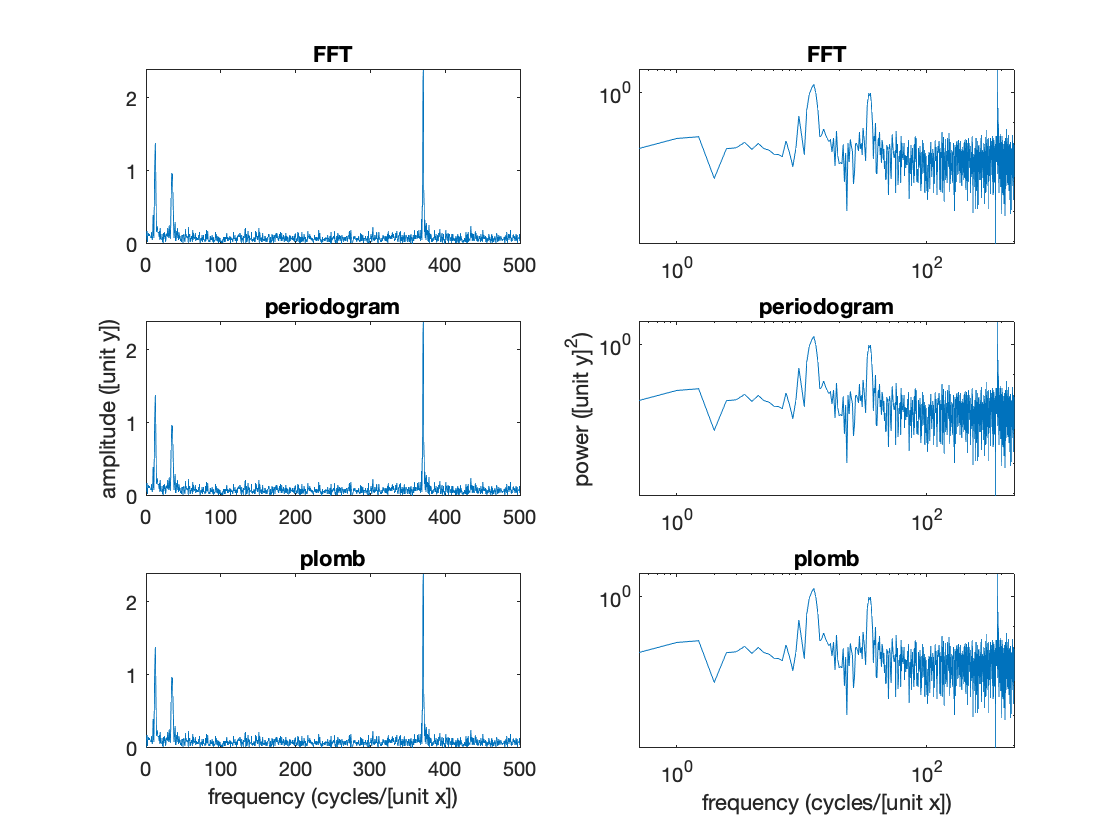


figure(2);clf
subplot(3,2,1)
plot(f,Af)
title('FFT')

subplot(3,2,2)
loglog(f,Pf)
title('FFT')

subplot(3,2,3)
plot(f,Ap);
ylabel('amplitude ([unit y])')
title('periodogram')

subplot(3,2,4)
loglog(f,Pp);
ylabel('power ([unit y]^2)')
title('periodogram')

subplot(3,2,5)
plot(f,Al);
xlabel('frequency (cycles/[unit x])')
title('plomb')

subplot(3,2,6)
loglog(f,Pl);
xlabel('frequency (cycles/[unit x])')
title('plomb')

#### For periodogram:

Amplitude of a 2-sided spectrum is 1/2 that of the 1-sided spectrum: $A_2 =\frac{1}{2}A$

The power spectrum produced by periodogram is 2-sided (periodogram does not allow 1-sided spectra with input frequency vector option), hence: $P_2 =A_2^2$

The one-sided power spectrum we want to obtain is: $P=A^2$

Solve for $P$ in terms of $P_2$:  $P={\left(2A_2 \right)}^2 =4A_2^2 =4P_2$.            

###                 
$$\begin{array}{l}
P_{\mathrm{periodogram},1-\mathrm{sided}} =4P_{\mathrm{periodogram},2-\mathrm{sided}} \\
A_{\mathrm{periodogram},1-\mathrm{sided}} =2\sqrt{P_{\mathrm{periodogram},2-\mathrm{sided}} }
\end{array}$$


*(Note: Periodogram produces 2-sided spectra when f-vector is set, but 1-sided spectra with nfft)*

#### For plomb:

From observations above, power of a 2-sided spectrum is *twice* that of the 1-sided spectrum: $P=2P_2$

The one-sided power spectrum is: $P=A^2$

The power spectrum produced by plomb is 2-sided, hence: ${2P}_2 =A^2$

Solve for $A$ in terms of $P_2$:             

###                 
$$\begin{array}{l}
P_{\textrm{plomb},1-\textrm{sided}} =2P_{\textrm{plomb},2-\textrm{sided}} \\
A_{\textrm{plomb},1-\textrm{sided}} =\sqrt{2P_{\textrm{plomb},2-\textrm{sided}} }
\end{array}$$


*(Note: this means that *$P_2 =\frac{1}{8}A_2^2$ !!!*)*